# Highway Lane Following: A Model-Based Design Example for ISO 26262:2018

This ADAS highway lane following example shows how you can use Simulink to apply a Model-Based Design workflow to an ISO 26262 ASIL D project. The example includes many of the development and verification lifecycle stages called out by ISO 26262, in particular, those required for software unit design, implementation, and verification.

Copyright 2021-2023 The MathWorks, Inc.

**License Requirements**

This example is designed for use on a personal computer with a Microsoft® Windows® operating system. 

The following product licenses are required in this case study:

- [IEC Certification Kit](matlab:web('https://www.mathworks.com/products/iec-61508.html','-browser');)

- [MATLAB®](matlab:web('http://www.mathworks.com/products/matlab/','-browser');)

- [Simulink®](matlab:web('http://www.mathworks.com/products/simulink/','-browser');)

The following product licenses are recommended to explore additional capabilities in this case study:

- [Automated Driving Toolbox™](https://www.mathworks.com/products/automated-driving.html)

- [Embedded Coder®](matlab:web('http://www.mathworks.com/products/embedded-coder/','-browser');)

- [MATLAB Coder™](matlab:web('http://www.mathworks.com/products/matlab-coder/','-browser');)

- [MATLAB Report Generator™](matlab:web('http://www.mathworks.com/products/ML_reportgenerator/','-browser');)

- [Model Predictive Control Toolbox™](https://www.mathworks.com/products/model-predictive-control.html)

- [Polyspace Bug Finder™](matlab:web('http://www.mathworks.com/products/polyspace-bug-finder/','-browser');)

- [Simulink Check™](matlab:web('http://www.mathworks.com/products/simulink-check/','-browser');)

- [Simulink Coder™](matlab:web('http://www.mathworks.com/products/simulink-coder/','-browser');)

- [Simulink Coverage™](matlab:web('http://www.mathworks.com/products/simulink-coverage/','-browser');)

- [Simulink Design Verifier™](matlab:web('http://www.mathworks.com/products/sldesignverifier/','-browser');)

- [Simulink Report Generator™](matlab:web('http://www.mathworks.com/products/SL_reportgenerator/','-browser');)

- [Requirements Toolbox™](matlab:web('http://www.mathworks.com/products/simulink-requirements/','-browser');)

- [Simulink Test™](matlab:web('http://www.mathworks.com/products/simulink-test/','-browser');)

- [Stateflow®](https://www.mathworks.com/products/stateflow.html)

- [System Composer™](https://www.mathworks.com/products/system-composer.html)

- [Vehicle Dynamics Blockset™](https://www.mathworks.com/products/vehicle-dynamics.html)

- [Control System Toolbox™](https://www.mathworks.com/products/control.html)

Note: Some of these products have other dependencies which you can find on [this page](https://www.mathworks.com/support/requirements/product-requirements-platform-availability-list.html).

This case study provides pregenerated reports that you can use to view design and verification/validation artifacts. It is important to note that hyperlinks in these reports might not work correctly. You will need to regenerate the reports to update their links to external objects.

## **Introduction**

The project shows you how to use Simulink to provide work products that are required as evidence for compliance with the normative clauses in Part 6 of ISO 26262:2018. The structure of the Simulink project mirrors these clauses, their prerequisites, and work products. 

Relevant normative process requirements from ISO 26262-8:2018 are taken into consideration as well for completeness and due to their high relevance for product development at all levels (i.e., system, hardware and software).

### ISO 26262-6:2018: Product development at the software level 

The following clauses are considered normative for the product development at the software level:

- Clause 5   : General topics for the product development at the software level

- Clause 6   : Specification of software safety requirements

- Clause 7   : Software architectural design

- Clause 8   : Software unit design and implementation

- Clause 9   : Software unit verification

- Clause 10 : Software integration and verification

- Clause 11 : Testing of the embedded software

- Annex   C :  Software configuration

The following Model-Based Design workflow shows the process activities defined in the ISO 26262-6:2018 clauses and identifies MathWorks tools that you can use to achieve the objectives of these clauses.  This workflow is used to develop the artifacts in the highway lane following case study. Additional details about this reference workflow is provided [here (requires an IEC Certification Kit license).](matlab:if(iec.internal.license('test','IEC Certification Kit')),web('certkitiec_mbd_iso26262.pdf','-browser');else,DAStudio.error('certqualkit:engine:IECMissLicense');end)

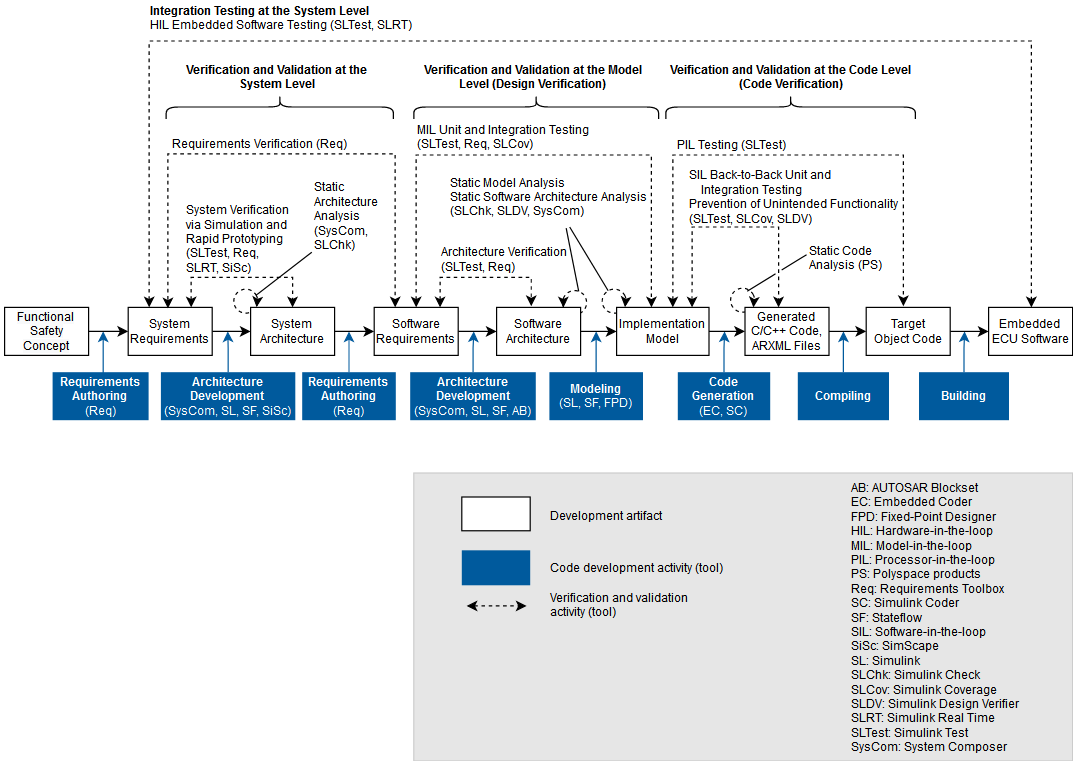 

The [Model Testing Dashboard](https://www.mathworks.com/help/slcheck/ug/model-testing-project.html) in [Simulink Check](https://www.mathworks.com/products/simulink-check.html) is used to assess the status and quality of model testing activities in the case study, in particular, requirements-based testing (RBT). RBT is a central element of model verification. When traceability links are established between requirements, model design elements, and test cases, you can use the Model Testing Dashboard to measure the extent to which the requirements are implemented and verified. The Model Testing Dashboard analyzes this traceability information and provides detailed metric measurements on the traceability, status, and results of these testing artifacts. An example of the requirement-based testing status is provided at the end of this script.

### ISO 26262-8:2018: Supporting processes

These normative clauses are relevant with regard to process-specific requirements for product development at the software level:

- Clause 6: Specification and management of safety requirements

- Clause 7: Configuration management

- Clause 8: Change management

- Clause 9: Verification

- Clause 10: Documentation management

- Clause 11: Confidence in the use of software tools

- Clause 12: Qualification of software components

**Note**: Process-specific requirements were considered in this case study. However, the work products needed to comply with these clauses are not presented here. For confidence in the use of software tools, use the IEC Certification Kit to generate required tool qualification reports.

- [Open the IEC Certification Kit (requires an IEC Certification Kit license)](matlab:if(iec.internal.license('test','IEC Certification Kit')),certkitiec;else,DAStudio.error('certqualkit:engine:IECMissLicense');end)

## Case Study: Highway Lane Following

A highway lane-following system steers a vehicle to travel within a marked lane. It also maintains a set velocity or safe distance from a preceding vehicle in the same lane. The system typically uses vision processing algorithms to detect lanes and vehicles from a camera. Vehicle detections from the camera are fused with detections from a radar to improve the ability to detect surrounding vehicles. The controller uses the lane detections, vehicle detections, and set speed to control steering and acceleration. The highway lane following feature in a vehicle is highly related to Conventional Cruise Control (CCC) and Adaptive Cruise Control (ACC) of a vehicle, where:

- CCC is a system capable of maintaining the speed of a vehicle as set by the driver

- ACC is a CCC system with additional capability to follow a leading vehicle while keeping a safe distance

As such, the highway lane following system can be considered as an ACC system that is augmented with lateral control to center the car within the current lane (i.e., automatic lane keeping feature).

A detailed description of the highway lane following controller and testing of its intended functionality can be found [here](https://www.mathworks.com/help/mpc/ug/highway-lane-following.html). This executable model served as the starting point for the development of the ISO 26262-compliant design, and verification/validation artifacts that are presented in this case study.

The assessment developed for the highway lane following controller was reused to verify the intended functionality of the integrated model. Fast forward to ISO 26262-6:2018 Clause 10 to view the assessment.

## Prerequisites for the product development at the software level

There are specific work products that must be available as prerequisites for initiating product development at the software level. Typically, these work products are produced during product development at the system level (ISO 26262-4:2018). These prerequisite work products shall be available:

- Technical safety requirement specification (ISO 26262-4:2018, 6.5.1)

- Technical safety concept (ISO 26262-4:2018, 6.5.2)

- System architecture design specification (ISO 26262-4:2018, 6.5.3)

In this case study, these prerequisite work products are assumed. Product development at the software level can be regarded as a Safety Element out of Context (SEooC), ISO 26262-10:2018, clause 9. The intended functionality of highway lane following is assumed to have an ASIL D. 

To view these prerequisites/assumptions:

- [Technical safety requirement specification (requires Requirements Toolbox license)](matlab:if(iec.internal.license('test','Requirements Toolbox')),open('TSRS.slreqx');else,DAStudio.error('certqualkit:engine:SLREQMissLicense');end)

- [System architecture design specification (requires System Composer license)](matlab:if(iec.internal.license('test','System Composer')),open('HLF_SystemArchitecture');else,DAStudio.error('certqualkit:engine:ZCMissLicense');end). The system architecture is also available in a [webview (requires MATLAB Report Generator).](matlab:rptview(fullfile(ProjArtifacts.webviewsPath,'HLF_SystemArchitecture','webview.html'));)

## ISO 26262-6:2018 Clause 5: General topics for the product development at the software level

The primary work product for this clause is documentation of the software development environment. This case study provides a template that is partially prepopulated with information that is relevant to the Model-Based Design and embedded development environment based on Simulink.

- [Open the documentation on software development environment (requires Microsoft Word)](matlab:web(ProjArtifacts.SWDevEnvTemplate, '-browser');)

## ISO 26262-6:2018 Clause 6: Specification of software safety requirements

Typically, software safety requirements are either:

- Derived directly from the technical safety requirements allocated to software

- Requirements that would lead to violation of technical safety requirements allocated to software if not fulfilled

- Added as a result of the safety-oriented analysis at the software architecture level (in subsequent phases)

ISO 26262-8:2018, clause 6.4.3.2 requires that you maintain traceability of safety requirements to the lower and upper hierarchical levels. To address this objective, you can use Requirements Toolbox to generate a **System** **Requirements Report **from each software requirement set. In the report, each software requirement has a section that provides its trace data to the system model and high-level system/software requirements.

In this case study, Requirements Toolbox is used to author the software safety requirements. To view these requirements in the project, click on the following link and select requirements set `SSRS`.

- [Open the software safety requirements (requires Requirements Toolbox license)](matlab:if(iec.internal.license('test','Requirements Toolbox')),open('SSRS.slreqx');else,DAStudio.error('certqualkit:engine:SLREQMissLicense');end)

Alternatively, you can view a pregenerated System Requirements Report (note 1) that is created from requirement set `SSRS` by using this link.

- [Open the pregenerated Software Requirements Report (Requires Microsoft Word)](matlab:web(ProjArtifacts.getReqReport('SSRS'),'-browser');)

Note 1: Requirements set `SSRS` contains requirements for the intended functionality of this case study. No ASIL decomposition is performed between the intended functionality and its corresponding safety mechanism.

Note 2: For demonstration purposes, only a sample of software requirements in requirements set `SSRS` is traced back to system level requirements in the `TSRS`.

% To generate the requirements report for a specific requirement set in the project,
% modify the name of the requirement set in the edit field. 
reqSetName = 'SSRS';
genReqReport(reqSetName);
 

### Verification of software safety requirements

You must also maintain verification artifacts for high-level software requirements that demonstrate suitability, compliance with system design and requirements, compliance and consistency with the technical safety requirements, accuracy and consistency, compatibility with hardware-software interface, verifiability, conformance to standards, and algorithm accuracy. Software requirements verification is typically performed by using a checklist (or similar means) to review the high-level software requirements, based on the adopted standards for software requirements.

Click this link for a checklist template:

- [Open the Requirements Review Checklist (requires Microsoft Excel) ](matlab:web(which('Requirements_Review_Checklist.xlsx'),'-browser');)

## ISO 26262-6:2018 Clause 7: Software Architectural Design

### Software Architectural Design Specification

System Composer and Simulink are used to develop the software architecture from the software requirements**.**

**Note**: ISO 26262-6:2018, Table 2 recommends semi-formal notations for all ASILs and highly recommends semi-formal notations for ASIL C and D. It specifically states that Simulink and Stateflow are suitable products to this end.

For more information on Simulink and System Composer, click the links below.

- [Help for Simulink](matlab:doc('simulink');)

- [Help for System Composer](matlab:doc('systemcomposer');)

In this case study, the software architectural design is presented in model `HighwayLaneFollowingController_SW_Arch`. This software architecture can be browsed from within the system architecture by traversing the highway lane following system block (which is allocated to software). 

- [Open the Highway Lane Following Software Architecture (requires Simulink, System Composer, Model Predictive Control Toolbox)](matlab:open_HighwayLaneFollowingController_SW_Arch;)

In the model, notice the BSW (basic software) and RTE (runtime environment) components; these are required to execute the application software on hardware. Top-level model component **HighwayLaneFollowingController** contains multiple lower-level models (i.e., software components). Because the source code is generated directly from these design models, the entire hierarchy of the **HighwayLaneFollowingController** model is considered to be the low-level software requirements. These design models are traceable to the high-level software requirements. 

You can use the project Dependency Analyzer to analyze dependencies in the architecture, including referenced models. For more information, click the links below.

- [Help for Simulink Project Management](matlab:web(fullfile(docroot, 'simulink/project-management.html')))

- [Help for Simulink Project Dependency Analyzer](matlab:web(fullfile(docroot, 'simulink/dependency-analysis.html')))

In the Highway Lane Following case study, a pregenerated dependency analysis report (note 1) is provided:

- [Open the pregenerated Model Dependency Report for Highway Lane Following System](matlab:web(fullfile(ProjArtifacts.SWArchPath,'reports','DependencyAnalyzerReportHLF.html'),'-new');)

% To view the dependency analysis for a specific Simulink model in the project,
% modify the name of the model in the edit field. 
modelName = "HighwayLaneFollowingController";
viewModelDependency(modelName);
 

**Note:** To fully define the software architecture and low-level software requirements, there are additional design and architecture components beyond these design models. For example, an additional algorithm is required to account for input processing, data exchange handling, and task scheduling. These components are not included as a part of this case study.

You can use Requirements Toolbox to trace the design models to the high-level software requirements and use Simulink Report Generator to generate a Software Design Description (SDD) report from each design model. In this report, a section is created for each Simulink system and subsystem to document its trace data to the software requirements. These reports provide a complete description of the design models, including:

- Snapshots of every level of the model

- Interfaces of every level of the model

- Block parameters and settings in every level of the model

- Block execution order of every level of the model

- Design variables of the model

- Trace data in every level of the model to the requirement documents

- Model configuration settings

- Glossary and report explanation

You can view a pregenerated SDD report (note 1) that was created from design models in this case study. Note that this report does not include model references.

- [Open the pregenerated Software Design Description report for Highway Lane Following (requires PDF Reader)](matlab:web(fullfile(fileparts(which('HighwayLaneFollowingController')),'documents','HighwayLaneFollowingController_SDD.pdf'),'-browser');)

% To generate the Software Design Description report from a specific Simulink model in the project,
% modify the name of the model in the edit field. 
% Note: you need to have all product dependencies installed in order to be
% able to generate the report, or otherwise some errors may show up during
% report generation. Use viewModelDependency(modelName) to retrieve
% product dependencies of a specific model.

modelName = 'ControllerModeSelector';
genSDD(modelName);
 

### Verification of the software architectural design specification

The architectural artifacts from the previous section are used in the verification of the software architecture. You can verify the architecture by using checklists, inspection, or simulation.

return to top

## ISO 26262-6:2018 Clause 8: Software Unit Design and Implementation

### Software Unit Design

With regard to software unit design, ISO 26262-6:2018, Table 5 recommends semi-formal notations for all ASILs and highly recommends semi-formal notations for ASIL C and D and states that Simulink and Stateflow are suitable products to this end.

For this case study, in software architectural design model `HighwayLaneFollowingController_SW_Arch, `you can view these software units in the **HighwayLaneFollowingController **component:

- [Open the ControllerModeSelector unit (requires Simulink)](matlab:open_ControllerModeSelector;) 

- [Open the EstimateLaneCenter unit (requires Simulink)](matlab:open_EstimateLaneCenter;) 

- [Open the FindLeadCar unit (requires Simulink)](matlab:open_FindLeadCar;) 

- [Open the LaneCenterCoordChange unit (requires Simulink)](matlab:open_LaneCenterCoordChange;) 

- [Open the MPCController unit (requires Simulink and Model Predictive Control Toolbox)](matlab:open_MPCController;). Alternatively, you can view the webview [here (requires MATLAB Report Generator)](matlab: rptview(fullfile(ProjArtifacts.webviewsPath, 'MPCController', 'webview.html'));)

- [Open the PreviewCurvature unit (requires Simulink)](matlab:open_PreviewCurvature;) 

- [Open the WDGBrakeTimeCalc unit (requires Simulink)](matlab:open_WDGBrakeTimeCalc;) 

- [Open the WDGBrakingLogic unit (requires Simulink and Stateflow)](matlab:open_WDGBrakingLogic;) 

- [Open the WDGTTCCalculation unit (requires Simulink)](matlab:open_WDGTTCCalculation;) 

### Software Unit Implementation

The source code representation of the software units is generated by using Embedded Coder. 

- [](matlab:web('http://www.mathworks.com/products/embedded-coder/','-browser');)[Help for Embedded Coder®](matlab:doc('ecoder');)

It is highly recommended that you generate the source code after verification of the design at the model level***. ***See Software unit verification at the model level.

You can view pregenerated Code Generation Reports (note 1) for the generated source code from design models in this case study by using these links:

- [Open the Code Generation Report for ControllerModeSelector](matlab:openCodeGenerationReport('ControllerModeSelector');)

- [Open the Code Generation Report for EstimateLaneCenter](matlab:openCodeGenerationReport('EstimateLaneCenter');)

- [Open the Code Generation Report for FindLeadCar](matlab:openCodeGenerationReport('FindLeadCar');)

- [Open the Code Generation Report for LaneCenterCoordChange](matlab:openCodeGenerationReport('LaneCenterCoordChange');)

- [Open the Code Generation Report for MPCController](matlab:openCodeGenerationReport('MPCController');)

- [Open the Code Generation Report for PreviewCurvature](matlab:openCodeGenerationReport('PreviewCurvature');)

- [Open the Code Generation Report for WDGBrakeTimeCalc](matlab:openCodeGenerationReport('WDGBrakeTimeCalc');)

- [Open the Code Generation Report for WDGBrakingLogic](matlab:openCodeGenerationReport('WDGBrakingLogic');)

- [Open the Code Generation Report for WDGTTCCalculation](matlab:openCodeGenerationReport('WDGTTCCalculation');)

% To generate code from a specific model/Software Unit in the project,
% modify the name of the software unit in the edit field. 
swUnitName = 'ControllerModeSelector';
genSrcCode(swUnitName);
 

**Note 1**: The code for these software units is generated - internal to genSrcCode function - by using command: `slbuild(modelName,'ModelReferenceCoderTargetOnly')`**, **where `modelName` is the name of the Simulink model. Generating code for software units (and components) as top models is dependent on the architectural design (e.g., the need to communicate with other components through a system bus or through the RTE).

**Note 2**: When generating code at higher levels (e.g., software components or models that contain software units as reference models), the code for the contained software units is not regenerated unless the software units has been modified. You can verify this by checking the time stamp for the corresponding files in the code generation report or in the source code files. 

**Note 3**: After executing functional tests in software-in-the-loop mode, the code generation report identifies the SIL utility C functions that are required to run the SIL simulations. However, source code already generated for software units does not change. You can verify this by checking the time stamp for the corresponding files in the code generation report.

return to top

## ISO 26262-6:2018 Clause 9: Software Unit Verification

Software unit verification is performed by using both dynamic testing (via simulation) and static testing (via inspection and analysis) methodologies. The following sections describe how you can perform this verification by using Simulink and how to generate software verification reports.

With Model-Based Design, software unit verification is typically performed first, at the model level, and then at the source and object code levels.

### Software Unit Verification at the Model level

#### Static Verification via Model Standards Checks

You can use the Simulink Check Model Advisor to verify the compliance of models with industry standards. You can use a Model Advisor configuration file to specify which checks to execute as part of the analysis. In this case study, Model Advisor configuration file `iso26262Checks` includes all the checks for verifying compliance with the Modeling Guidelines for High-Integrity Systems, as well as additional checks that are applicable for ISO 26262. 

For more information on Simulink Check, click the link below.

- [Help for Simulink Check](matlab:doc('slcheck');)

You can view pregenerated Model Advisor Reports (note 1) for the design models in this case study:

- [Open the Model Advisor report for ControllerModeSelector (HTML Report)](matlab:web(ProjArtifacts.getUnitMStdChksHTML('ControllerModeSelector'),'-new');)

- [Open the Model Advisor report for EstimateLaneCenter (HTML Report)](matlab:web(ProjArtifacts.getUnitMStdChksHTML('EstimateLaneCenter'),'-new');) 

- [Open the Model Advisor report for FindLeadCar (HTML Report)](matlab:web(ProjArtifacts.getUnitMStdChksHTML('FindLeadCar'),'-new');) 

- [Open the Model Advisor report for MPCController (HTML Report)](matlab:web(ProjArtifacts.getUnitMStdChksHTML('MPCController'),'-new');) 

- [Open the Model Advisor report for PreviewCurvature (HTML Report)](matlab:web(ProjArtifacts.getUnitMStdChksHTML('PreviewCurvature'),'-new');) 

- [Open the Model Advisor report for WDGBrakeTimeCalc (HTML Report)](matlab:web(ProjArtifacts.getUnitMStdChksHTML('WDGBrakeTimeCalc'),'-new');) 

- [Open the Model Advisor report for WDGBrakingLogic (HTML Report)](matlab:web(ProjArtifacts.getUnitMStdChksHTML('WDGBrakingLogic'),'-new');) 

- [Open the Model Advisor report for WDGTTCCalculation (HTML Report)](matlab:web(ProjArtifacts.getUnitMStdChksHTML('WDGTTCCalculation'),'-new');) 

% To run model advisor ISO 26262 checks for a specific model/Software Unit in the project,
% modify the name of the software unit in the edit field. 
swUnitName = 'ControllerModeSelector';
checkModelStds(swUnitName);
 

**Note 1**: Notice that these Model Advisor reports may include check warnings. These modeling guideline violations in the software unit are intentional and intended for demonstration purposes. 

**Note 2**: Any violations that cannot be corrected shall be justified. 

In addition, you can use the Model Advisor to obtain model metrics for the software units. Pregenerated Model Advisor Reports (note 1) for the design models in this case study are below.

- [Open the Model Metrics report for ControllerModeSelector (HTML Report)](matlab:web(ProjArtifacts.getUnitModelMetricsHTML('ControllerModeSelector'),'-new');)

- [Open the Model Metrics report for WDGBrakingLogic (HTML Report)](matlab:web(ProjArtifacts.getUnitModelMetricsHTML('WDGBrakingLogic'),'-new');) 

% To run model advisor to compute metrics for a specific model/Software Unit in the project,
% modify the name of the software unit in the edit field. 
swUnitName = 'ControllerModeSelector';
computeModelMetrics(swUnitName);
 

#### Static Verification via Design Error Detection

Simulink Design Verifier uses formal methods to identify potential design errors in software unit models. You can use static analysis to detect these types of errors:

- Dead logic 

- Integer overflow 

- Division by zero 

- Violation of the specified minimum and maximum values 

- Out of bound array access 

For more information on Simulink Design Verifier, click the link below.

- [Help for Simulink Design Verifier](matlab:doc('sldv');)

For this case study, these pregenerated Design Error Detection Reports (note 1) specify design errors in the models:

- [Open the Design Error Detection Report for ControllerModeSelector (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitDesErrsPDF('ControllerModeSelector'),'-browser');) Or in [HTML](matlab:web(ProjArtifacts.getUnitDesErrsHTML('ControllerModeSelector'),'-browser');)

- [Open the Design Error Detection Report for EstimateLaneCenter (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitDesErrsPDF('EstimateLaneCenter'),'-browser');) Or in  [HTML](matlab:web(ProjArtifacts.getUnitDesErrsHTML('EstimateLaneCenter'),'-browser');)

- [Open the Design Error Detection Report for WDGBrakingLogic (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitDesErrsPDF('WDGBrakingLogic'),'-browser');) Or in [HTML](matlab:web(ProjArtifacts.getUnitDesErrsHTML('WDGBrakingLogic'),'-browser');)

The analysis report for **EstimateLaneCenter** includes multiple instances of possible division by zero. These errors are intentionally provided for demonstration purposes. It is important to note that you can add justifications to the analysis findings (e.g., acceptable dead logic).

You may also observe that that some design models are not compatible with Simulink Design Verifier. For these, other model verification methods can be more suitable. Partially compatible design models can be partially verified by using Simulink Design Verifier. 

By default, a Simulink Design Verifier analysis runs for a maximum of 300 seconds. You can modify the execution time before running the analysis. 

% To run Simulink Design Verifier to detect design errors for a specific model/Software Unit in the project,
% modify the name of the software unit in the edit field. 
swUnitName = 'WDGBrakingLogic';
detectDesignErrs(swUnitName);
 

#### Functional Verification using MIL simulation

**Note**: Only software units **ControllerModeSelector **and** WDGBrakingLogic** are used to demonstrate the use of MIL simulation for functional verification.

A major advantage of Model-Based Design is that when the software unit design is developed in the corresponding models of these software units, you can verify the design models against the high-level software requirements without having to develop any hardware and/or software. Specifically, Simulink Test provides a framework for creating simulation test harnesses, authoring and executing test cases, and generating a report from the test results. For more information on Simulink Test, click the link below.

- [Help for Simulink Test](matlab:doc('sltest');)

For this case study, Simulink Test was used to create test file `ControllerModeSelector.mldatx` , which verifies **ControllerModeSelector** against its high-level software requirements. In this file, test suite `Requirement-based testing` contains an example test case that performs functional requirement-based testing for the unit under test. Input and corresponding output data for the unit under test are specified in separate MAT files; this data is used by the test manager to compare simulation results with the baseline data.

Similarly, Simulink Test test file `WDGBrakingLogic.mldatx` verifies **WDGBrakingLogic** against the high-level software requirements that it implements. In this file, test suite `Requirement-based testin`g contains an example test case that performs functional requirement-based testing for the unit under test. A test sequence is defined in the harness model and simulation output for the input sequence is verified against the expected results (which are retrieved from an Excel sheet).

**Note**: In both test files, suites for `interface`, `fault injection`, and `resource usage testing` are reserved for further development.

For both test suites the test procedure:

- Executes the test harness for the software unit and verifies that it operates properly

- Generates a test report of the software unit simulation cases, including:

-         Aggregated test results with a pass/fail summary 

-         Aggregated model coverage results 

-         Test case results, including the pass/fail outcome 

-         Information for each test case, including trace data to requirements 

-         Simulation output for each test case, including plots 

- Generates a model coverage report (Calculated by using Simulink Coverage)

For more information on Simulink Coverage, click the link below.

- [Help for Simulink Coverage](matlab:doc('slcoverage');)

Click the following links to open test files, test harnesses, and pregenerated reports (note 1) for this case study. If desired, you can [open the test files for all units (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open('ControllerModeSelector_Test.mldatx');open('EstimateLaneCenter_Test.mldatx');open('FindLeadCar_Test.mldatx');open('MPCController_Test.mldatx');open('PreviewCurvature_Test.mldatx');open('WDGBrakingLogic_Test.mldatx');open('WDGBrakeTimeCalc_Test.mldatx');open('WDGTTCCalculation_Test.mldatx');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end). Note that some test files are empty and are provided for demonstration purposes only.

**ControllerModeSelector:**

- [Open the test file for software unit ControllerModeSelector (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open('ControllerModeSelector_Test.mldatx');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end)

- [Open the test harness for ControllerModeSelector (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open_system('ControllerModeSelector_Harness');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end) 

- [Open the pregenerated High-Level Simulation Test Results Report for ControllerModeSelector (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitMILResultsHLRPDF('ControllerModeSelector'),'-browser');)

- [Open the pregenerated High-Level Model Coverage Report for ControllerModeSelector (in HTML)](matlab:web(ProjArtifacts.getUnitMCovHLRHTML('ControllerModeSelector'),'-new');) 

**WDGBrakingLogic**:

- [Open the test file for software unit WDGBrakingLogic (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open('WDGBrakingLogic_Test.mldatx');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end)

- [Open the test harness for WDGBrakingLogic (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open_system('WDGBrakingLogic_Harness');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end)

- [Open the pregenerated High-Level Simulation Test Results Report for WDGBrakingLogic (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitMILResultsHLRPDF('WDGBrakingLogic'),'-browser');)

- [Open the pregenerated High-Level Model Coverage Report for WDGBrakingLogic (in HTML)](matlab:web(ProjArtifacts.getUnitMCovHLRHTML('WDGBrakingLogic'),'-new');). For demonstration purposes, this report includes a missing model coverage. Notice that several transitions in the Stateflow design model have been identified with an uncovered decision. 

% To run tests for a specific model/Software Unit in the project,
% modify the name of the software unit in the edit field. 
swUnitName = 'ControllerModeSelector';
verifyModel2Reqs(swUnitName);
 

### Software Unit Verification at the Code level

#### Static Verification of Source Code via Coding Standards Checks

Polyspace Bug Finder provides the capability to check source code for conformance to standards. For more information, click the link below. 

- [Help for Polyspace Bug Finder](matlab:doc('bugfinder');)

In this case study, the checks used by Polyspace Bug Finder to verify against coding rules are defined in configuration file `MISRA_C_2012_ACG`. This configuration exercises all available checks against MISRA C:2012 directives and rules that are critical for automatically generated code. To review the current state of compliance of Embedded Coder with MISRA C:2012 (only directives and rules that have the "mandatory" and "required" categories), see [MISRA C:2012 Compliance Information Summary Tables](matlab:web(fullfile(docroot,'ecoder/ug/misra-c2012-compliance-information-summary-tables.html'));). 

You can view the pregenerated Polyspace Bug Finder Coding Standards Reports (note 1) for the source code generated from the design models of some software units:

- [ControllerModeSelector (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitCStdChksPDF('ControllerModeSelector'),'-browser');). Note that this report contains a justification for two deviations to rule 21.1 in `rtwtypes.h`. 

- [EstimateLaneCenter (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitCStdChksPDF('EstimateLaneCenter'),'-browser');) 

- [LaneCenterCoordChange (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitCStdChksPDF('LaneCenterCoordChange'),'-browser');) 

- [PreviewCurvature (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitCStdChksPDF('PreviewCurvature'),'-browser');) 

- [WDGBrakeTimeCalc (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitCStdChksPDF('WDGBrakeTimeCalc'),'-browser');) 

- [WDGBrakingLogic (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitCStdChksPDF('WDGBrakingLogic'),'-browser');) 

- [WDGTTCCalculation (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitCStdChksPDF('WDGTTCCalculation'),'-browser');) 

For a quick reference, Open the Code Generation Report for [ControllerModeSelector](matlab:web(ProjArtifacts.getImplPathHTML('ControllerModeSelector'),'-new');) and [WDGBrakingLogic](matlab:web(ProjArtifacts.getImplPathHTML('WDGBrakingLogic'),'-new');).

% To run Polyspace Bug Finder to check generated code for MISRA compliance for a specific model/Software Unit in the project,
% modify the name of the software unit in the edit field. 
swUnitName = 'ControllerModeSelector';
checkCodeStds(swUnitName);
 

#### Functional Verification of Target Code in PIL simulation

You can use Embedded Coder to verify executable object code that is generated from models using processor-in-the-loop (PIL) simulations. With this method, you can exercise the executable object code on the target computer by reusing the test cases that were previously developed for verifying the design models. For more information, see the explanation of [SIL and PIL Simulations](matlab:web(fullfile(docroot,'ecoder/ug/about-sil-and-pil-simulations.html#responsive_offcanvas'));) in the help for Embedded Coder.

PIL Simulation is typically performed to provide evidence for correct code transformations (i.e., model –> generated source code –> target object code), and is done by

- testing semantic equivalence between models and object code running on target hardware 

- verifying achieved numerical equivalence/accuracy 

Software-in-the-loop (SIL) simulations can be considered an intermediate step that provides evidence for correct transformation from model to generated source code. A SIL simulation compiles the source code needed to run on the host computer, and as such, the executable object code does not match that of the target hardware. However, while a SIL simulation does not exercise the executable object code on the target hardware, it does use the source code generated for the final target.

Performing PIL simulations at the software unit level is not always necessary, such as when these conditions are met:

- SIL simulations are performed for all software units

- Sufficient integration testing is performed on target hardware

- A qualified/certified target compiler is used

#### Functional Verification of Source Code in SIL simulation

Due to hardware constraints, processor-in-the-loop (PIL) simulations are not supported in this example. For demonstration purposes, software-in-the-loop (SIL) simulations are used and the focus will be on the code generated for **ControllerModeSelector** and **WDGBrakingLogic**.

Simulink Test provides a mechanism for executing test cases via SIL/PIL simulations. You can reuse test files `ControllerModeSelector.mldatx` and `WDGBrakingLogic.mldatx` to verify the generated executable object code. By setting the override of model simulation mode to `Software-in-the-Loop (SIL)`, the test files perform these steps:

- Executes all test cases

- Generates a test report of executed test cases, including:

- Aggregated test results with a pass/fail summary

- Aggregated code coverage results

- Result for each test case, including its pass/fail outcome

- Information for each test case, including its trace data to requirements

- SIL simulation output for each test case, including plots

- Generates a code coverage report

The code coverage achieved by the SIL tests is calculated using code coverage capability in Simulink Coverage. 

To reopen the test files, review the pregenerated SIL Test reports (note 1), and/or view the actual results, click these links. If you want to run the previously developed test cases in SIL mode, first change the `Simulation mode` in each test case to `Software-in-the-loop (SIL)`. Examples of missing code coverage are included intentionally for demonstration purposes.

**ControllerModeSelector:**

- [Open the test file for ControllerModeSelector (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open('ControllerModeSelector_Test.mldatx');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end)

- [Open the pregenerated High-Level SIL Test Results Report for ControllerModeSelector (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitSPILRBTResPDF('ControllerModeSelector','SIL',true),'-browser');)

- [Open the pregenerated High-Level Code Coverage Report for ControllerModeSelector (in HTML)](matlab:web(ProjArtifacts.getUnitRBTCCovHTML('ControllerModeSelector','SIL'),'-new');)

- [Open the High-Level SIL test Results for ControllerModeSelector (requires Simulink Test license)](matlab:if(license('test','simulink_test')),open(ProjArtifacts.getUnitSPILRBTResFile('ControllerModeSelector','SIL',true));end)

**WDGBrakingLogic:**

- [Open the test file for WDGBrakingLogic (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open('WDGBrakingLogic_Test.mldatx');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end)

- [Open the pregenerated High-Level SIL Test Results Report for WDGBrakingLogic (requires PDF Reader)](matlab:web(ProjArtifacts.getUnitSPILRBTResPDF('WDGBrakingLogic','SIL',true),'-browser');)

- [Open the pregenerated High-Level Code Coverage Report for WDGBrakingLogic (in HTML)](matlab:web(ProjArtifacts.getUnitRBTCCovHTML('WDGBrakingLogic','SIL'),'-new');) 

- [Open the High-Level SIL test Results for WDGBrakingLogic (requires Simulink Test license)](matlab:if(license('test','simulink_test')),open(ProjArtifacts.getUnitSPILRBTResFile('WDGBrakingLogic','SIL',true));end)

% To verify generated code for a specific software unit against the requirements it implements,
% modify the name of the software unit in the edit field. 
% Note: this verification reuses the same tests applied at the model level.
swUnitName = 'ControllerModeSelector';
verifyObjCode2Reqs(swUnitName, 'SIL');
 

### Low-Level Test Generation

The test case generation capability in Simulink Design Verifier autogenerates test cases based on the model and code coverage data collected from simulation test cases. These test cases shall be reviewed and, where necessary, the pass/fail criteria shall be refined.

For this case study, review the following for **WDGBrakingLogic**:

- [Open the Test Case Generation Report for WDGBrakingLogic](matlab:web(ProjArtifacts.getUnitSLDVTestGenReport('WDGBrakingLogic'),'-browser');) (in PDF), see note 1.

- [Open the automatically created test file for WDGBrakingLogic(requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open('WDGBrakingLogic_SLDV_Based_Test.mldatx');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end). This test files was created by Simulink Design Verifier for organizing the generated low-level test cases. For reference, the original test file is [here (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open('WDGBrakingLogic_Test.mldatx');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end).

- [Open the automatically created test harness for WDGBrakingLogic (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open_system('WDGBrakingLogic_Harness_SLDV');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end)

% You can generate tests that complement your coverage at the model level,
% using the following command. 
% Modify the name of the software unit in the edit field. 
swUnitName = 'WDGBrakingLogic';
genLowLevelTests(swUnitName);
 

To run the low-level test cases for **WDGBrakingLogic** in MIL mode, run the automatically generated test file above. Review these reports (note 1):

- [Open the pregenerated Low-Level Test Results Report for WDGBrakingLogic (in PDF)](matlab:web(ProjArtifacts.getUnitMILResultsLLRPDF('WDGBrakingLogic'),'-browser');)

- [Open the pregenerated Low-Level Model Coverage Report for WDGBrakingLogic](matlab:web(ProjArtifacts.getUnitMCovLLRHTML('WDGBrakingLogic'),'-new');)

% You can use the generated tests to verify your software unit models using the following command. 
% Modify the name of the software unit in the edit field. 
% Note: you may need to verify the generated tests against requirements implemented by the software unit model
swUnitName = 'WDGBrakingLogic';
verifyModel2LowLevelTests(swUnitName);
 

Notice that the pregenerated model coverage report only records the coverage achieved by the low-level tests. To determine the coverage results accomplished by running both the high-level and low-level tests, either 

- Combine tests in one test file and rerun OR

- Aggregate coverage results from each test 

The results of aggregating model coverage results from the high- and low-level tests is provided in the following report. This cumulative report contains the original coverage produced by the high-level tests, the complementary coverage yielded by the low-level tests, and the overall coverage. In the reports, the cumulative code coverage is now at 100%. It is obvious that the missing code coverage that was not achieved by the high-level tests is now addressed by the low-level tests. Please note that missing high-level tests are excluded intentionally for demonstration purposes.

- [Open the pregenerated Cumulative Model Coverage Report for WDGBrakingLogic](matlab:web(ProjArtifacts.getUnitMCovMRGHTML('WDGBrakingLogic'),'-new');)

% You can use the generated tests to verify your software unit models using the following command. 
% Modify the name of the software unit in the edit field. 
% Note: you may need to verify the generated tests against requirements implemented by the software unit model
swUnitName = 'WDGBrakingLogic';
mergeModelCoverage(swUnitName);
 

**Note**: In some cases, 100% model coverage does not mean full structural coverage at the code level. In these cases, Simulink Design Verifier can be used to generate tests that cover the missing code coverage.

## ISO 26262-6:2018 Clause 10: Software Integration and Verification

The Highway Lane Following case study does not currently include detailed activities for software integration and verification. Generally, software units are integrated during this development stage in a way that is compliant with the hierarchical structure of the software architecture. At each integration level, interfaces and dynamic aspects of the design are verified.

### Integrated Software Components

[Open the fully integrated Highway lane following controller component (requires Simulink and Model Predictive Control Toolbox)](matlab:open_HighwayLaneFollowingController;) and review these intermediate integration levels for the case study:

- [Open the WDGBrakingController component (requires Simulink)](matlab:open_WDGBrakingController;)

- [Open the Lane Following Data Conditioning component (requires Simulink)](matlab:open_DetectMIOLaneCenter;)

- [Open the Lane Following Controller component (requires Simulink and Model Predictive Control Toolbox)](matlab:open_LF_Controller;)

- Generated code for integrated models [HighwayLaneFollowingController](matlab:web(ProjArtifacts.getImplPathHTML('HighwayLaneFollowingController', true),'-new');), [WDGBrakingController](matlab:web(ProjArtifacts.getImplPathHTML('WDGBrakingController'),'-new');), [LF_Controller](matlab:web(ProjArtifacts.getImplPathHTML('LF_Controller'),'-new');), and [DetectMIOLaneCenter](matlab:web(ProjArtifacts.getImplPathHTML('DetectMIOLaneCenter'),'-new');). Note that code generated for referenced models can be viewed from within the code generation for the parent model.

% To generate code from a specific software component (not the top model) in the project,
% modify the name of the software component in the edit field. 
swComponentName = 'WDGBrakingController';
genSrcCode(swComponentName);
% To generate code from the top model with, uncomment the following line
% and press the push button.
% genSrcCode('HighwayLaneFollowingController', 'TopModel');
 

### **Verification Specification of Software Components**

**Note**: For this case study, only verification of the fully integrated highway lane following component is provided. 

The verification of integrated software can be performed during all intermediate integration levels. You can use Simulink Check, Simulink Design Verifier and Polyspace Bug Finder to perform static verification of the software components. However, special considerations have to be taken not to repeat verification activities that were already performed for software units and intermediate integration models. Verification considerations include:

- You can configure Simulink Check and Polyspace Bug Finder to ignore referenced models during analysis

- When Simulink Design Verifier proves the absence of some design errors (i.e., design errors are proven VALID) or the presence of DEAD LOGIC at the software unit level, you can safely consider the same as VALID (or DEAD LOGIC) at the integration level.

- When Simulink Design Verifier identifies the presence of design errors or proves absence of DEAD LOGIC at the software unit level, these results may not be true for integrated models. Therefore, you should reanalyze these objectives at the integration level

- When you are able to prove the absence of design errors and absence of dead logic at the software unit level, you do not need to perform the same analysis on the integration level given that: (a) integration introduces no additional logic (i.e., when integration means interconnecting software units only) and (b) full structural coverage is achieved for dynamic testing at the unit and integration levels, as per ISO 26262 recommended structural coverage metrics

Similar to the dynamic testing of software units, testing of the intended functionality is facilitated by using Simulink Test.

- [Open the highway lane following controller metric assessment model (requires Simulink, Simulink Test, MPC toolbox, Vehicle Dynamics Blockset, Automated Driving Toolbox)](matlab:open_HighwayLaneFollowingControllerAssessment;) 

**Note**: The assessment model defines some variables with the PostLoadFcn callback so that the model can simulate with a pre-defined driving scenario. The following Simulink test file iterates over several driving scenarios to test the fully integrated model.

- [Open the test file for HighwayLaneFollowingController (requires Simulink Test license)](matlab:if(iec.internal.license('test','Simulink Test')),open('HighwayLaneFollowingControllerMetricAssessments.mldatx');else,DAStudio.error('certqualkit:engine:SLTESTMissLicense');end)

### **Verification Report of Software Components**

The verification results of the integrated model during MIL simulation are gathered and exported to a verification report similar to verification results at the unit level. The pregenerated test results are as follows:

- [View the pregenerated test results for model simulation (requires PDF reader)](matlab:web(fullfile(ProjArtifacts.compVerifResultsPath,'HLFCTestResults.pdf'),'-browser'))

You can easily reuse same tests for SIL testing by setting the Simulation mode in the test file for the HighwayLaneFollowingController above to `Software-in-the-Loop (SIL)`.

return to top

## ISO 26262-6:2018 Clause 11: Testing Embedded Software

Activities for testing the embedded software are not included in the current version of the example. 

In general, this validation is performed using Hardware-in-the-loop testing, Restbus simulation, mule or lab vehicles.

return to top

## ISO 26262-6:2018 Annex C: Software Configuration

This project contains several software units and components that use configurable values, such as vehicle parameters in the **MPCController **software unit. 

Configured software units were verified as discussed in the software unit verification section. The configuration data was verified to be within range of the admissible data (defined [here](matlab:web(fullfile(docroot, 'mpc/ref/pathfollowingcontrolsystem.html')))), see ISO 26262-6:2018, clause C.4.5. Simulink automatically checks compliance of the vehicle parameters against the range of admissible data. 

return to top

## ISO 26262-8:2018, Clause 11 Confidence in the use of Software tools (Tool Qualification)

The IEC Certification Kit can be used to qualify many of the verification tools explained in this example. For more information, see the [IEC Certification Kit.](matlab:web('http://www.mathworks.com/products/iec-61508.html','-browser');)

## Analysis of Testing Artifacts using Model Testing Dashboard

You can use the [Model Testing Dashboard](https://www.mathworks.com/help/slcheck/ug/model-testing-project.html) capability in [Simulink Check](https://www.mathworks.com/products/simulink-check.html) to assess the status and quality of model testing activities. The status of this case study is available in [this PDF file](matlab:web(fullfile(ProjArtifacts.dashboardsPath,'ModelTestingDashboardStatus.pdf'),'-browser');), which is exported by using the Model Testing Dashboard.

To set up the dashboard for the project:

    1) Define project labels for your design models.  For this example project,

                -  "SWUnit" was used for each of the 9 software unit models.

                - "SWComponent" was used for each of the 4 Integration models 

    2) Open the dashboard by using one of these approaches:  

- On the Project tab, click **Model Testing Dashboard** under the Tools section.

- At the command line, enter [`modelTestingDashboard`](matlab:modelTestingDashboard).  

    3) Close the **Project Requires Analysis** window.

    4) Select **Options** from the dashboard toolstrip.

    5) Select the category and label for your design models.  For example:

            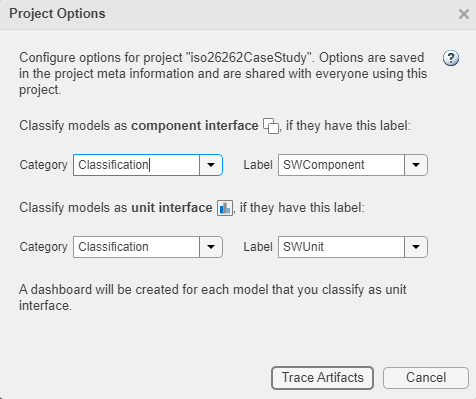

    6) Select **Trace Artifacts**

The dashboard displays metric results for the model selected in the **Artifacts** panel. To collect metric data for the model, click **Collect Results**. To collect metrics for all models in the project, click **Collect Results** > **Collect All Results**. Collecting data for a metric requires a license for the product that supports the underlying artifacts, such as Requirements Toolbox, Simulink Test, or Simulink Coverage. However, a license is not required to view existing metric data.

## Workflow Automation with Continuous Integration

This project includes an example framework that shows how you can use Jenkins jobs for continuous integration (CI) to fully automate the execution of code generation, software verification and report generation activities. 

- [Open the Jenkins Continuous Integration example for this project](matlab:web(ProjArtifacts.CI_UG,'-browser');)

## Conclusion

This example illustrates how you can use Model-Based Design to satisfy many objectives of ISO 26262-6:2018. The key advantages of applying Model-Based Design using Simulink for ISO 26262 include:

- Complete traceability and improved consistency among requirements, architecture, design, source code, and test cases

- Continuous and uninterrupted refinement of system and software requirements and architectural designs

- Consistency of data throughout the development lifecycle

- Improved software quality through automatic code generation (reduced risk of coding errors)

- Continuous and early validation of requirements as soon as the design process begins

- Continuous verification of static aspects of architectures, e.g., through simulation and automatic consistency checks

- Continuous and early verification of designs (efficient elimination of errors at early stages and before hardware becomes available)

- Integrated workflow for scenario testing of ADAS applications through sensor, environment and plant modeling and simulations

- Easy modification, refactoring and maintenance of development artifacts and automatically generated work products

- Confidence of use in qualified software tools throughout the safety/development lifecycle

**Notes**

(1) Hyperlinks in pregenerated reports may not work correctly. Reports need to be regenerated to update their links to external objects.